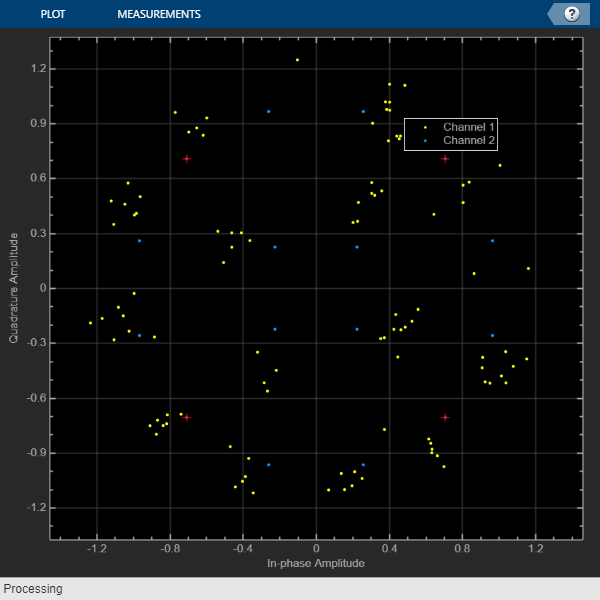

% Generate training data with DVBS-APSK modulation, SRRC, and AWGN in
% passband. SNR is specificed for a range. 

M = 16;
nb = 10014; %number of integers 

EbNo = 10; 
packets = 100; 
window = 4; 

rng(0)

%communication things 
constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',1, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',100);
agc = comm.AGC('DesiredOutputPower', 1/8, 'MaxPowerGain', 400);  
PA = comm.MemorylessNonlinearity('Method', 'Saleh model');

txfilter = comm.RaisedCosineTransmitFilter(); %tx srrc
rxfilter = comm.RaisedCosineReceiveFilter(); %rx srrc
LO = dsp.SineWave("Frequency", 1.5e9, "ComplexOutput", true, "SampleRate", (1e-6)/8, "SamplesPerFrame", 8*nb); 
y = LO(); %up conversion
    
for BO = [1,7,30]
    if BO == 1
        PA.InputScaling = 9;
    elseif BO == 7
        PA.InputScaling = 3.5; 
    else 
        PA. InputScaling = -20
    end 

    msg = randi([0 sum(M)-1], nb, 1);
    symbols = dvbsapskmod(msg, M, 's2x'); 
    txfilterData = txfilter(symbols); 
    txfilterData = PA(txfilterData);
    txData = txfilterData.*y; %upconvert
    
    rxData = txData.*conj(y); %down convert
    rxData = agc(rxData); 
    rx = rxfilter(rxData); %SRRC filter
    
    d = finddelay(symbols, rx); %need to remove delay before windowing
    rx = rx((d+1):end); %get rid of filter delay 
    symbols = symbols(1:(end-d));
    
    train_data = makeInputMat(rx,window);
    train_data = train_data(:,1:end-window);
    symbols = symbols(1+window:end);
    target = round([real(symbols) imag(symbols)],5)';
    
    x_train = zeros(size(train_data,1),size(train_data,2)*packets);
    y_train = zeros(size(target,1),size(target,2)*packets);
    
    %validation data
    msg = randi([0 sum(M)-1], nb, 1);
    symbols = dvbsapskmod(msg, M, 's2x');
    txfilterData = txfilter(symbols); %srrc
    txfilterData = PA(txfilterData);
    txData = txfilterData.*y; %upconvert
    
    rxData = txData.*conj(y); %down convert
    rxData = agc(rxData); 
    rx = rxfilter(rxData); %SRRC filter
    
    d = finddelay(symbols, rx); %need to remove delay before windowing
    rx = rx((d+1):end); %get rid of filter delay 
    symbols = symbols(1:(end-d));
    
    val_data = makeInputMat(rx,window);
    val_data = val_data(:,1:end-window);
    symbols = symbols(1+window:end);
    val_target = round([real(symbols) imag(symbols)],5)';
      
    %train data
    for iter = 1:packets
        x_train(:,((iter-1)*size(train_data,2)+1):(iter*size(train_data,2))) = train_data;
        y_train(:,((iter-1)*size(target,2)+1):(iter*size(target,2))) = target;
        if iter ~= packets
            msg = randi([0 sum(M)-1], nb, 1);
            symbols = dvbsapskmod(msg, M, 's2x');
            txfilterData = txfilter(symbols); %srrc
            txfilterData = PA(txfilterData);
            txData = txfilterData.*y; %upconvert
            
            rxData = txData.*conj(y); %down convert
            rxData = agc(rxData); 
            rx = rxfilter(rxData); %SRRC filter
    
            d = finddelay(symbols, rx); %need to remove delay before windowing
            rx = rx((d+1):end); %get rid of filter delay 
            symbols = symbols(1:(end-d)); %align with rx
    
            train_data = makeInputMat(rx,window);
            train_data = train_data(:,1:end-window);
            symbols = symbols(1+window:end);
            target = round([real(symbols) imag(symbols)],5)';
        end 
    end 
    
    x_train = x_train'; 
    y_train = y_train';
    
    val_data = val_data'; 
    val_target = val_target'; 
    
    filename_train = sprintf('DVBSAPSK_data_BO_%d', BO);
    save(filename_train, 'x_train', 'y_train', 'val_data', 'val_target'); 
   
    constDiagram([rx(1:100), symbols(1:100)]); %double check

end 

%Generate testing data, similar to above code but only one sequence of
%integers are generated 
rng(0); 
M=16;
window = 4;
nb = 100014;

%communication things 
constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',1, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',100);
LO = dsp.SineWave("Frequency", 1.5e9, "ComplexOutput", true, "SampleRate", (1e-6)/8, "SamplesPerFrame", 8*nb); 
y = LO(); %up/down conversion
PA = comm.MemorylessNonlinearity('Method', 'Saleh model'); %high power amplifier 
agc = comm.AGC('DesiredOutputPower', 1/8, 'MaxPowerGain', 400); 

txfilter = comm.RaisedCosineTransmitFilter(); %tx srrc
rxfilter = comm.RaisedCosineReceiveFilter(); %rx srrc

for BO = [1,7,30]
    %adjust back off
    if BO == 1
        PA.InputScaling = 9;
    elseif BO == 7
        PA.InputScaling = 3.5; 
    else 
        PA. InputScaling = -20; 
    end 
    for i = 1:10
        msg = randi([0 sum(M)-1], nb, 1);
        symbols = dvbsapskmod(msg, M, 's2x'); 
        txfilterData = txfilter(symbols); 
        txfilterData = PA(txfilterData);
        txData = txfilterData.*y; %upconvert
       
        rxData = txData.*conj(y); %down convert
        rxData = agc(rxData); %gain control 
        rx = rxfilter(rxData); %SRRC filter 
        
        d = finddelay(symbols, rx); %need to remove delay before windowing
        rx = rx((d+1):end); %get rid of filter delay 
        symbols = symbols(1:(end-d));
        
        train_data = makeInputMat(rx,window);
        train_data = train_data(:,1:end-window);
        symbols = symbols(1+window:end);
        target = round([real(symbols) imag(symbols)],5)';
        
        train_data = train_data'; 
        
        filename_test = sprintf('DVBSAPSK_pred_%d_%d', [BO,i]); 
        save(filename_test, 'train_data', 'target'); 
    end 
end

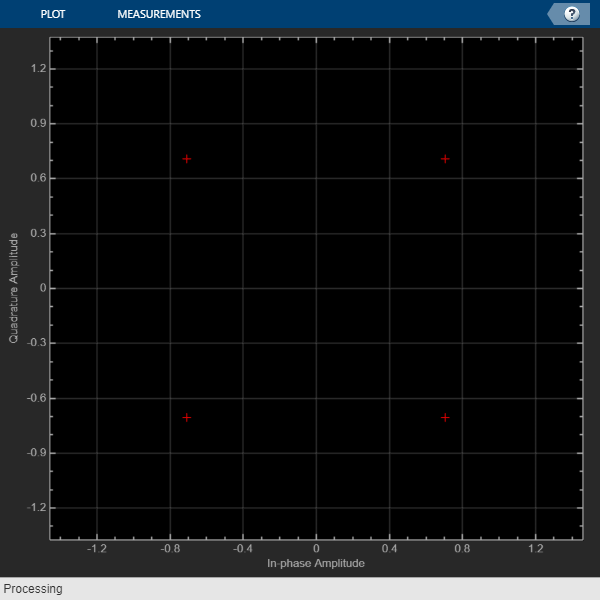

ans = 3.5000e-04

%Evaluate 
M = 16;
nb = 100010;
constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',1, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',100, 'ChannelNames', {'NN Input', 'TX Symbols', 'NN Output'});
agc = comm.AGC('DesiredOutputPower', 1/8, 'MaxPowerGain', 400);  
LO = dsp.SineWave("Frequency", 1.5e9, "ComplexOutput", true, "SampleRate", (1e-6)/8, "SamplesPerFrame", 8*nb); 
y = LO(); %up/down conversion
PA = comm.MemorylessNonlinearity('Method', 'Saleh model');
PA.InputScaling = 9; 

for BO = [1,7,30]
    ber_NN = zeros(1,10);
    for i = 1:10 
            cd(sprintf('BO_%d',BO))
            f_og = sprintf('DVBSAPSK_out_%d_%d', [BO, i]);
            load(f_og)
            cd .. 
            
            f =  sprintf('DVBSAPSK_pred_%d_%d', [BO,i]);
            load(f)
            
            pred = complex(pred(:,1), pred(:, 2));
            target = target';
            target_cp= complex(target(:,1), target(:, 2));
            
            %BER
            demodData_NN = dvbsapskdemod(pred, M, 's2x'); 
            demodData_ideal = dvbsapskdemod(target_cp, M, 's2x');
            
            demodData_NN = cast(demodData_NN,'like',demodData_ideal); %matching type
            
            %calculate BER
            data_bit = int2bit(demodData_ideal, 4); %convert to bit
            output_bit = int2bit(demodData_NN, 4);%convert to bit
            
            d = finddelay(data_bit,output_bit); 
            errorRate = comm.ErrorRate('ReceiveDelay', abs(d));
            err = errorRate(data_bit, output_bit); %get bit error
            ber_NN(i)= err(1)*100;
    end 
    mean(ber_NN) %get average BER
    %plot performance on constellation diagram
    msg = randi([0 sum(M)-1], nb, 1);
    symbols = dvbsapskmod(msg, M, 's2x'); 
    txfilterData = txfilter(symbols); 
    txfilterData = PA(txfilterData);
    txData = txfilterData.*y; %upconvert
    
    rxData = txData.*conj(y); %down convert
    rxData = agc(rxData); 
    rx = rxfilter(rxData); %SRRC filter
    
    d = finddelay(symbols, rx); %need to remove delay before windowing
    rx_seq = rx((d+1):end); %get rid of filter delay 
    
    constDiagram([rx_seq,target_cp, pred]); %need to include rx symbols
end 

%debugging -- ignore
M = 16; 
nb = 100000;

constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',1, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',100);

PA = comm.MemorylessNonlinearity('Method', 'Saleh model');
PA.InputScaling = -20; 

txfilter = comm.RaisedCosineTransmitFilter(); %tx srrc
rxfilter = comm.RaisedCosineReceiveFilter(); %rx srrc
LO = dsp.SineWave("Frequency", 1.5e9, "ComplexOutput", true, "SampleRate", (1e-6)/8, "SamplesPerFrame", 8*nb); 
y = LO(); %up conversion

agc = comm.AGC('DesiredOutputPower', 1/8, 'MaxPowerGain', 400); 

cd BO_1
f = 'DVBSAPSK_out_1_1'; 
load(f); cd .. 

pred = complex(pred(:,1), pred(:, 2));

msg = randi([0 sum(M)-1], nb, 1);
symbols = dvbsapskmod(msg, M, 's2x'); 
txfilterData = txfilter(symbols); 
txfilterData = PA(txfilterData); 
txData = txfilterData.*y; %upconvert

rxData = txData.*conj(y); %down convert
rxData = agc(rxData);
rx = rxfilter(rxData); %SRRC filter

constDiagram(rx)